# Detecting arbitrary shape

Read and display image file

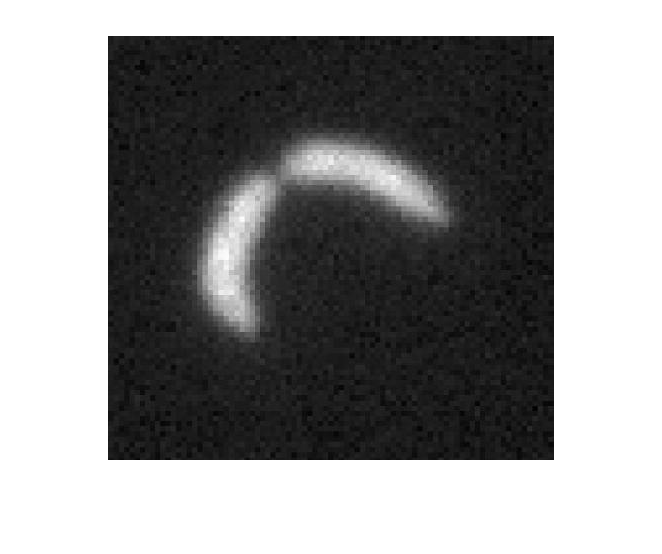

img1 = imread('CCfew2.jpg');
imshow(img1);

Detect edge

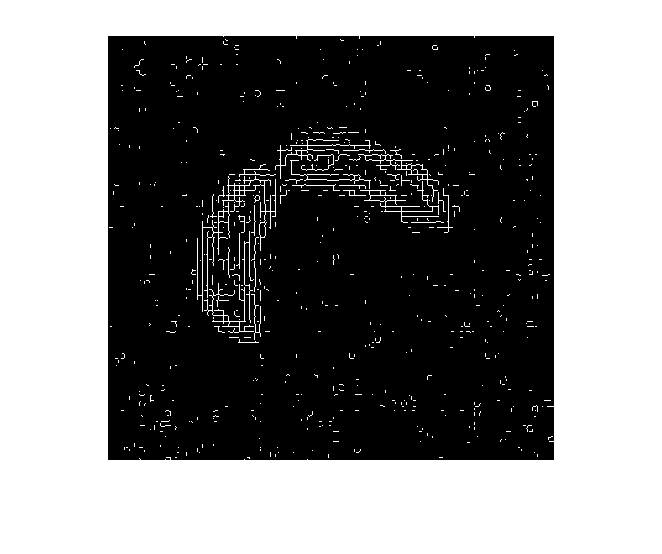

bw1 = edge(img1, 'Sobel');
imshow(bw1);

Dilate image

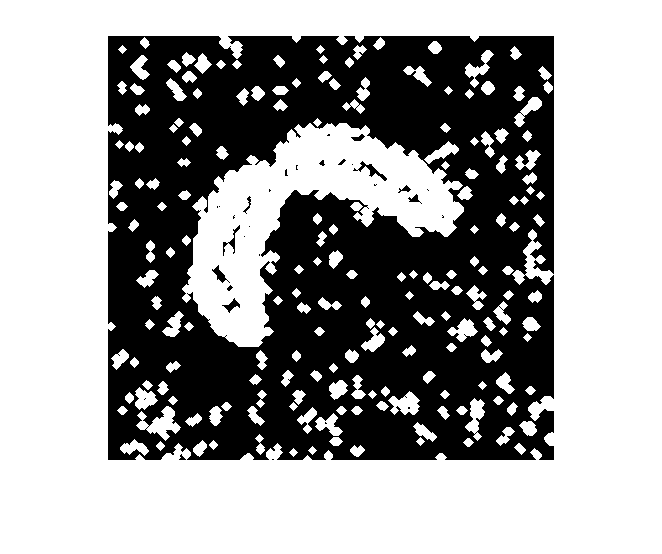

sediam = strel('diamond', 4);
bw_dil = imdilate(bw1, sediam);
imshow(bw_dil);

Fill holes and open

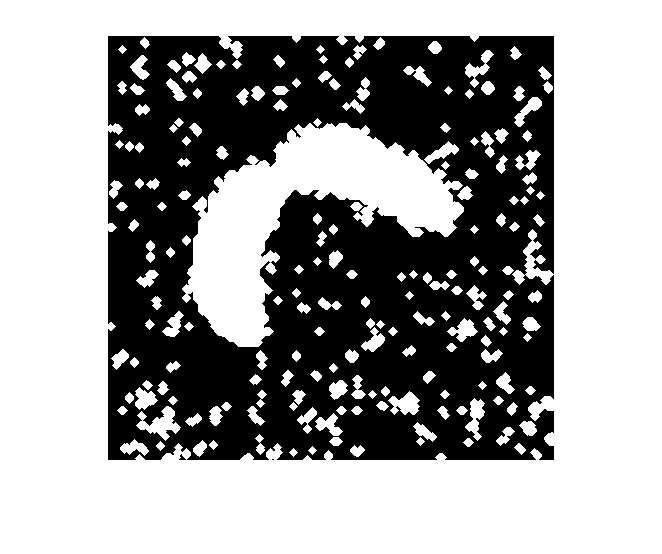

bw_fill = imfill(bw_dil, 'holes');
imshow(bw_fill);

Remove noise pixels

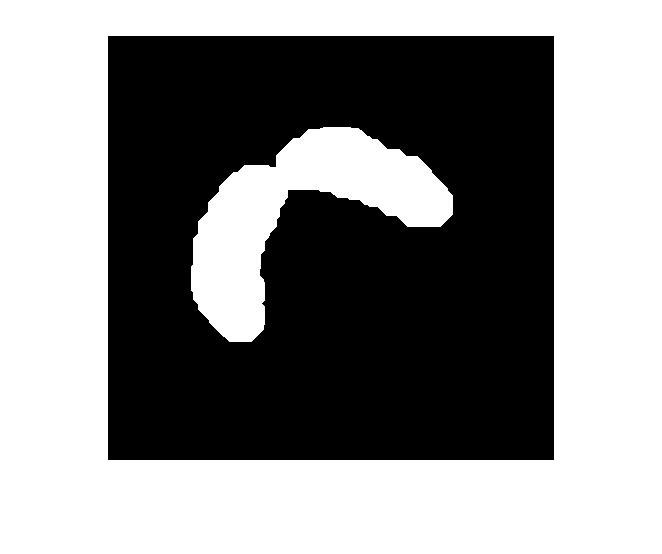

sedisk = strel('disk', 22);
bw_open = imopen(bw_fill, sedisk);
imshow(bw_open);

Smoothen object

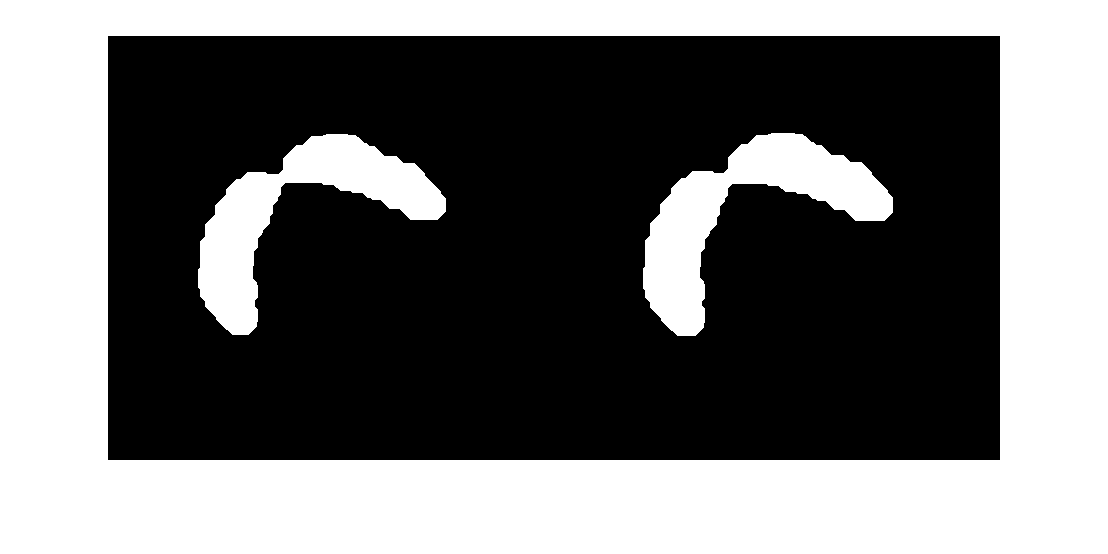

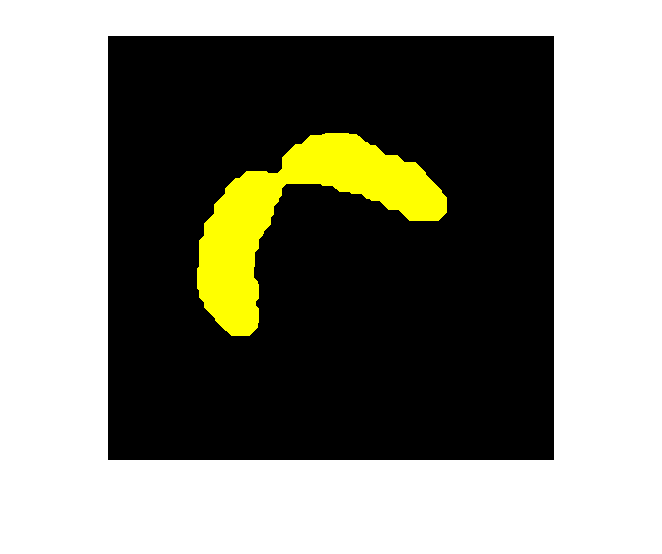

sedisk = strel('disk', 8);
bw_smooth = imerode(bw_open, sedisk);
imshow(bw_smooth);

Create perimeter

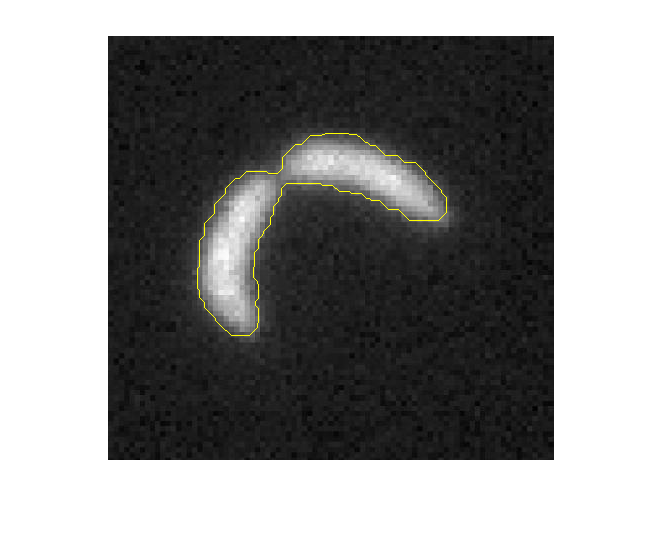

bw_line = bwperim(bw_smooth);
img2 = imoverlay(img1, bw_line); 
imshow(img2)